# Dimensionality Reduction

Our (input) dataset is a matrix, $\mathcal{X}$with $n$ rows and $d$ columns.  Clustering can be seen as trying to find and exploit structure among the **rows** of the data, while dimensionality reduction works on the **columns** (i.e. the features).

Why reduce dimensionality?

- Reduces time complexity: Less computation

- Reduces space complexity: Less parameters

- Saves the cost of observing the feature

- Simpler models are more robust on small datasets

- More interpretable; simpler explanation

- Data visualization (structure, groups, outliers, etc) if plotted in 2 or 3 dimensions

## Classes of Techniques

Feature selection: Choosing $k<d$ important features, ignoring the remaining $d-k$

- Subset selection algorithms

Feature extraction: Project the original $x_i, i=1,\ldots,d$ dimensions to new $k<d$ dimensions, $z_j, j=1,\ldots,k$

-   Principal components analysis (PCA), Fisher's linear discriminant analysis (LDA), multi-dimensional scaling, t-Stochastic Neighbor Embedding

## Feature (subset) selection

There are $2^d$ subsets of $d$ features

**Forward search:** Add the best feature (greedily) at each step

- Set of features $F$ initially $\emptyset$.

- At each iteration, find the best new feature: $j = \arg \min_i E(F \cup x_i)$

- Add $x_j$ to $F$  if $E(F \cup x_j) < E(F)$ 

This is a Hill-climbing algorithm with $O(d^2)$complexity

**Backward search:** Start with all features and remove one at a time, if possible.

In the Matlab stats&ML toolbox, the function `sequentialfs()` implements these. 

**Floating search:** (Add *k*, remove *l*)

**Feature Extraction (aka Transformation)**

There are a huge variety of techniques!  We will look at the most well known/used.

**Principal Component Analysis (PCA)**

Find a low-dimensional space such that when $\mathbf{x}$ is projected there, information loss is minimized.

The projection of $\mathbf{x}$ on the direction of $\mathbf{w}$ is: $z = \mathbf{w}^T \mathbf{x}$ 

Find $\mathbf{w}$ such that Var($z$) is maximized (projection to a line (1D)).  More generally, find the matrix $W$

You can think of this as performing a rotation of the coordinate system describing $\mathbf{x}$ such that the axes are successively aligned with the **directions of greatest variance** in the data.

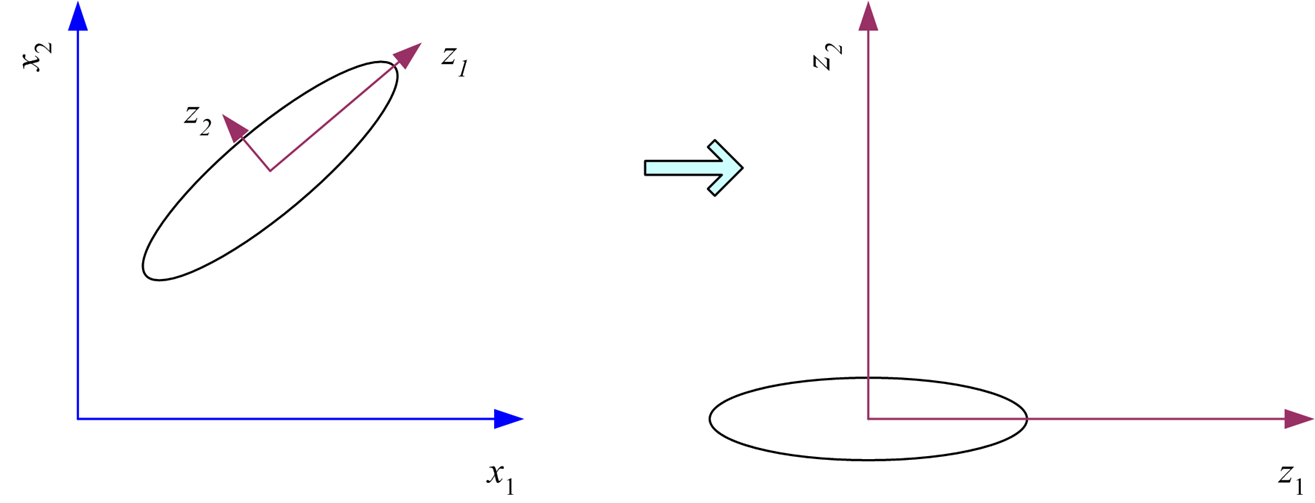

Note: the data should be centred first by subtracting the mean.

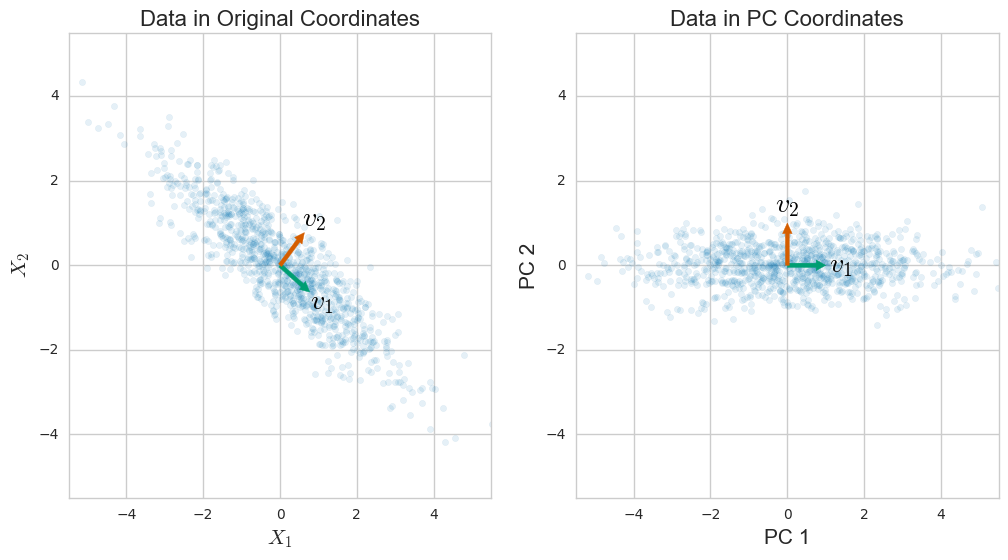 [Source: [https://intoli.com/blog/pca-and-svd/]](https://intoli.com/blog/pca-and-svd/])

To reduce the dimensionality (to $k<d$), the projection is performed using the first $k$ columns of $W$rather then the whole matrix.

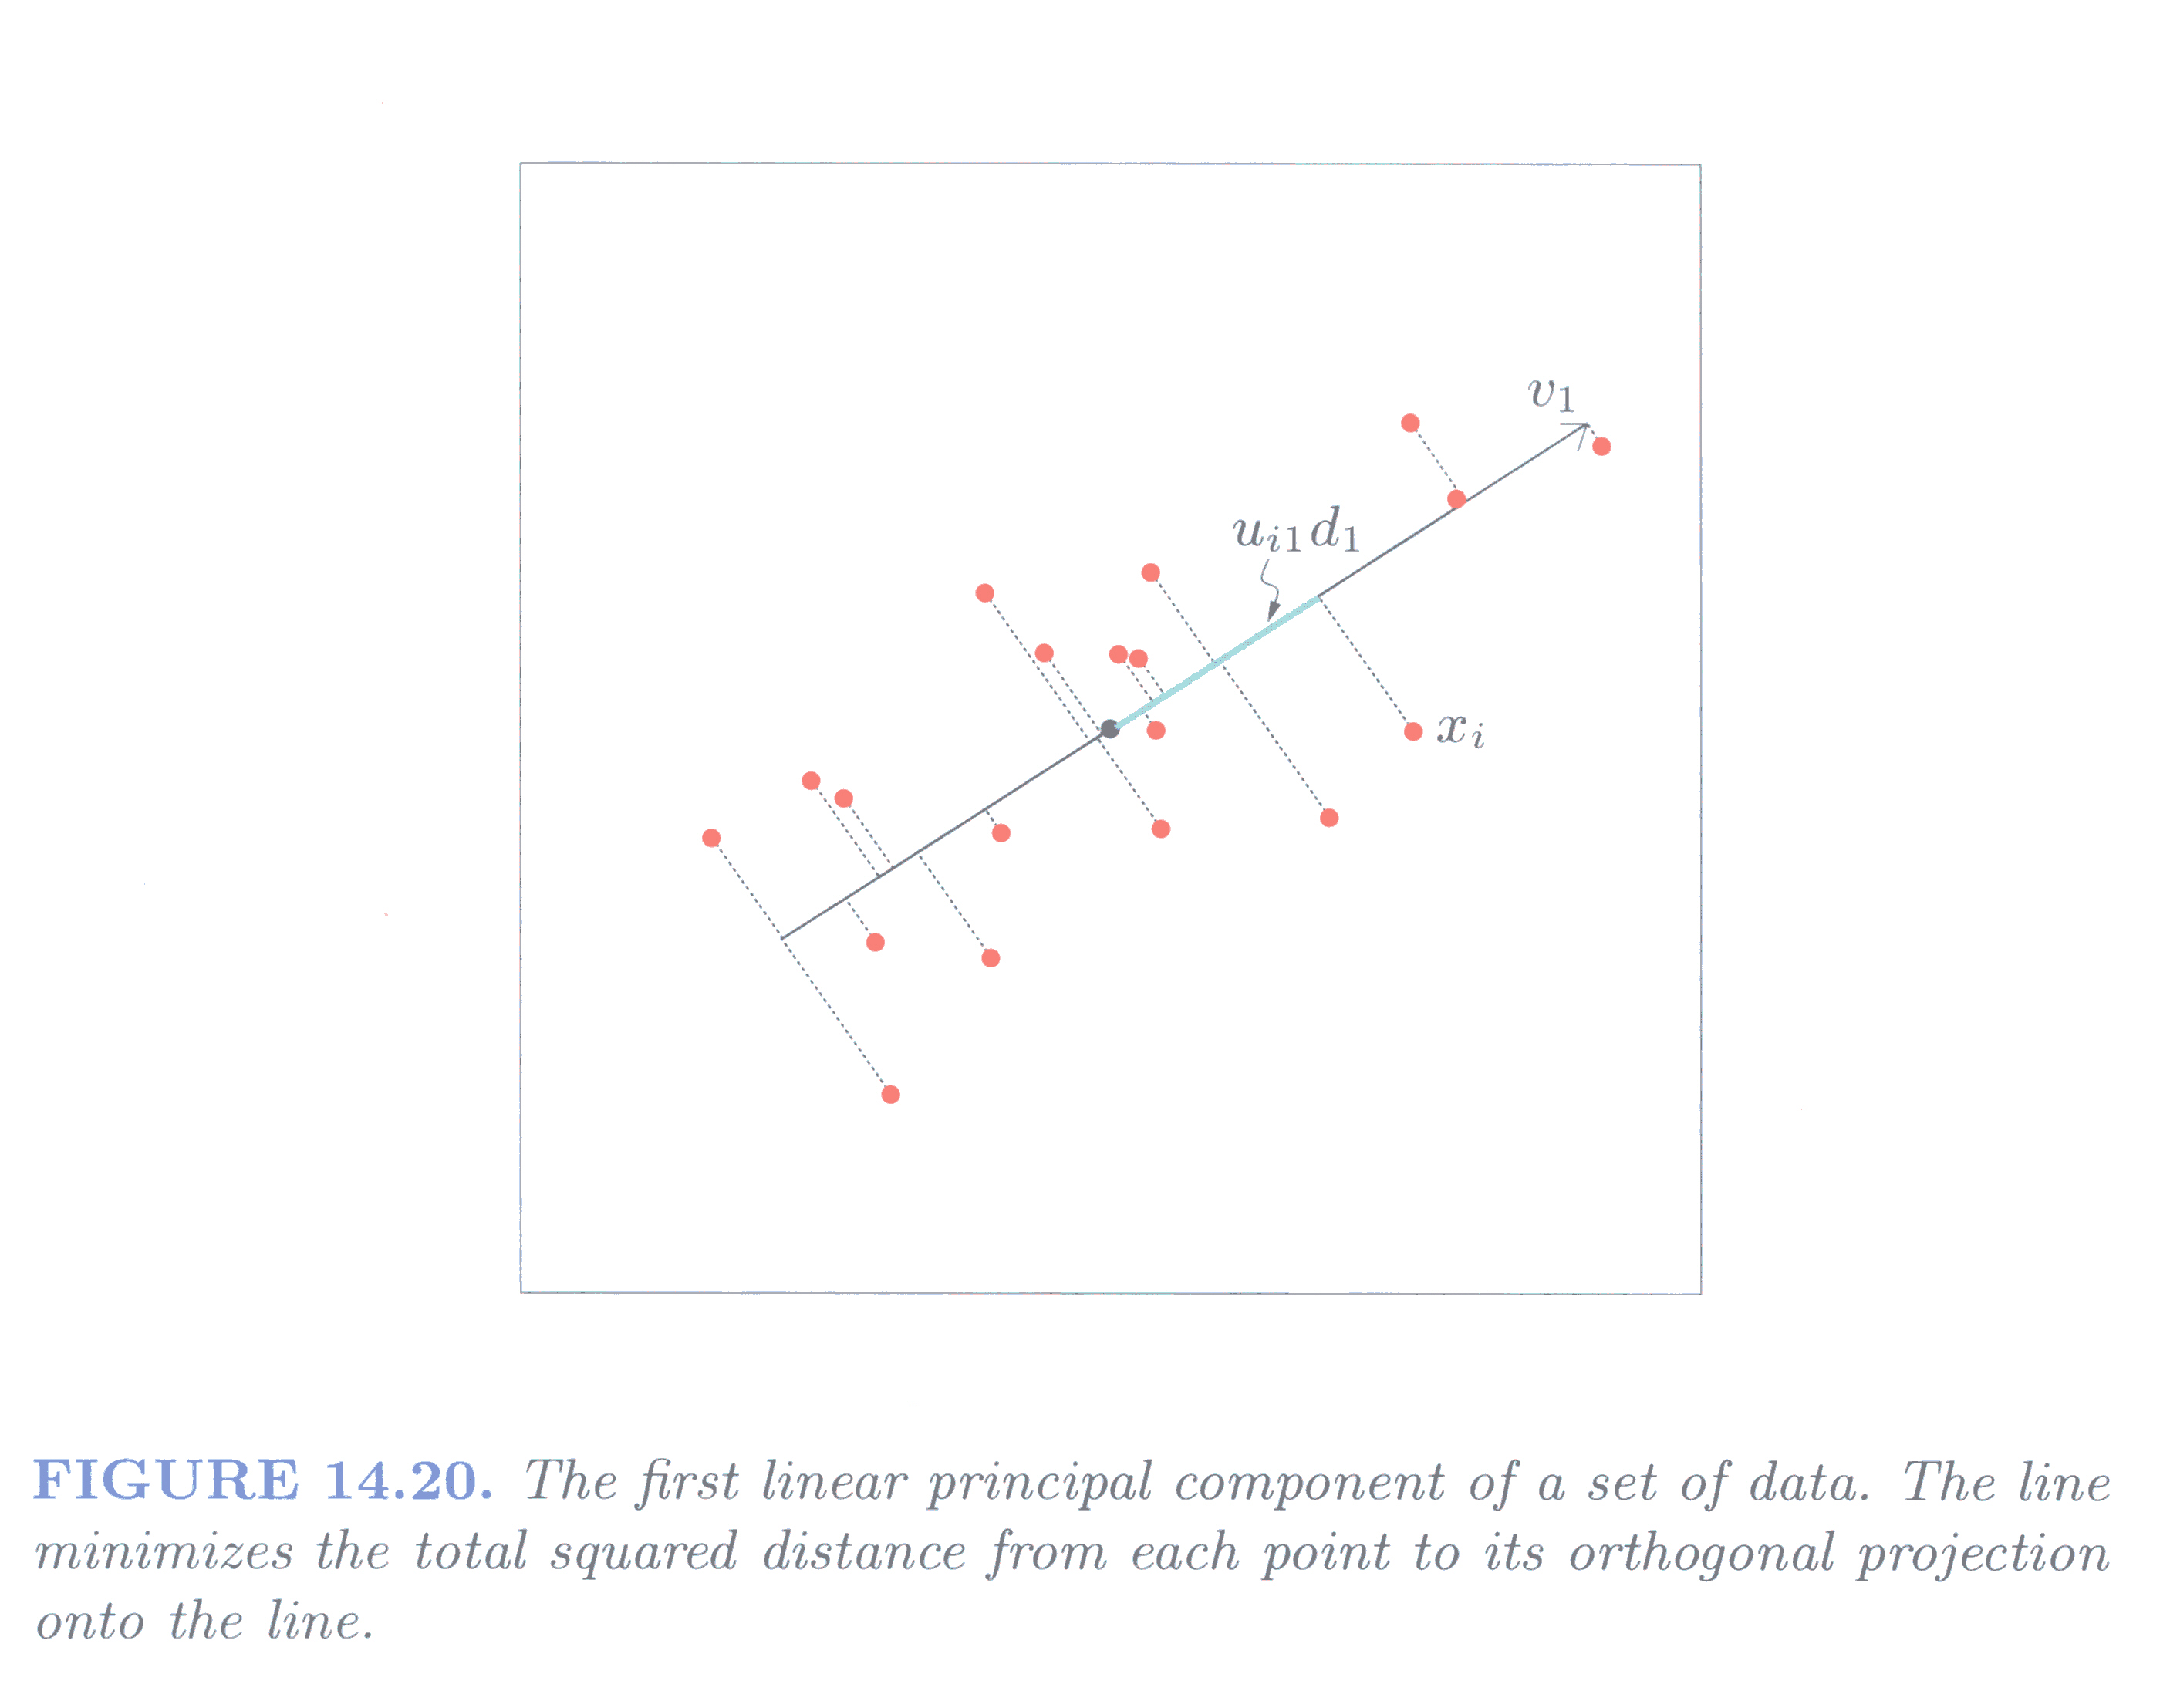

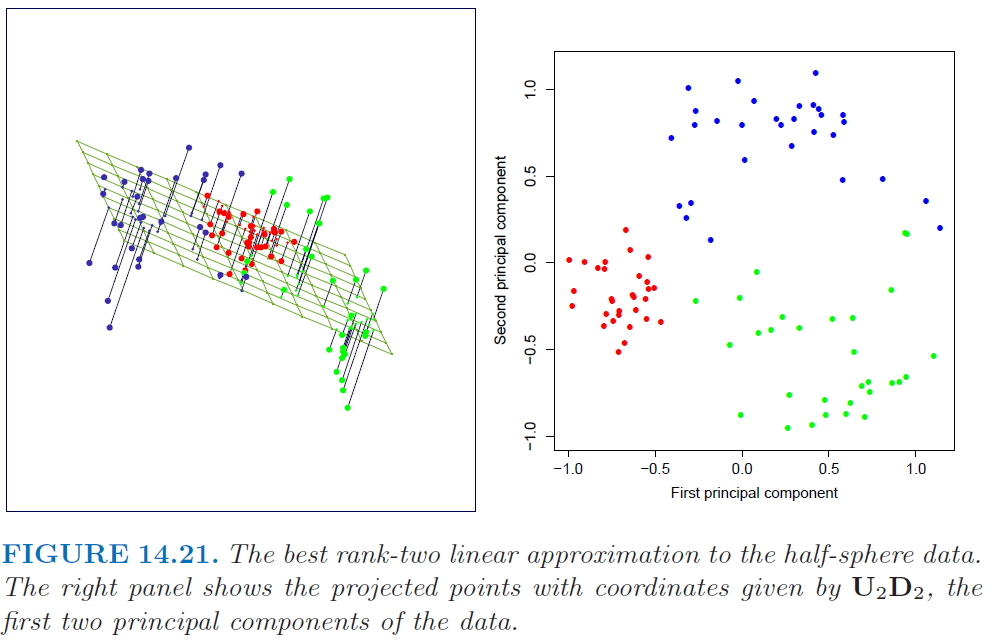

PCA performs a linear projection and finding $W$is a solved problem.  The easiest way is to find the eigenvectors (and eigenvalues!) of the covariance matrix of the data, $\mathcal{X}$. If you are familiar with linear algebra, it can also be done (more efficiently) via a singular value decomposition.

The eigenvectors are the principal components.  The eigenvectors $\lambda_i$ explain the amount of variance that is being captured by eacheigenvector.  A projection onto the first $k$ principal components will capture (or explain) a fraction,

$\frac{\lambda_1+\lambda_2+\ldots+\lambda_k}{\lambda_1+\lambda_2+\ldots+\lambda_k+\ldots+\lambda_d}$  of the total variance (times by 100 for a  percentage).

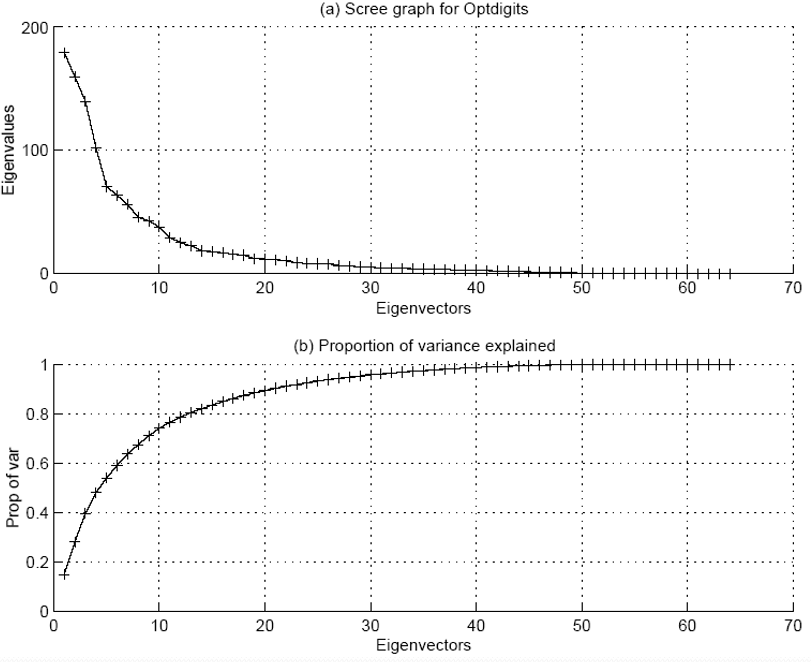     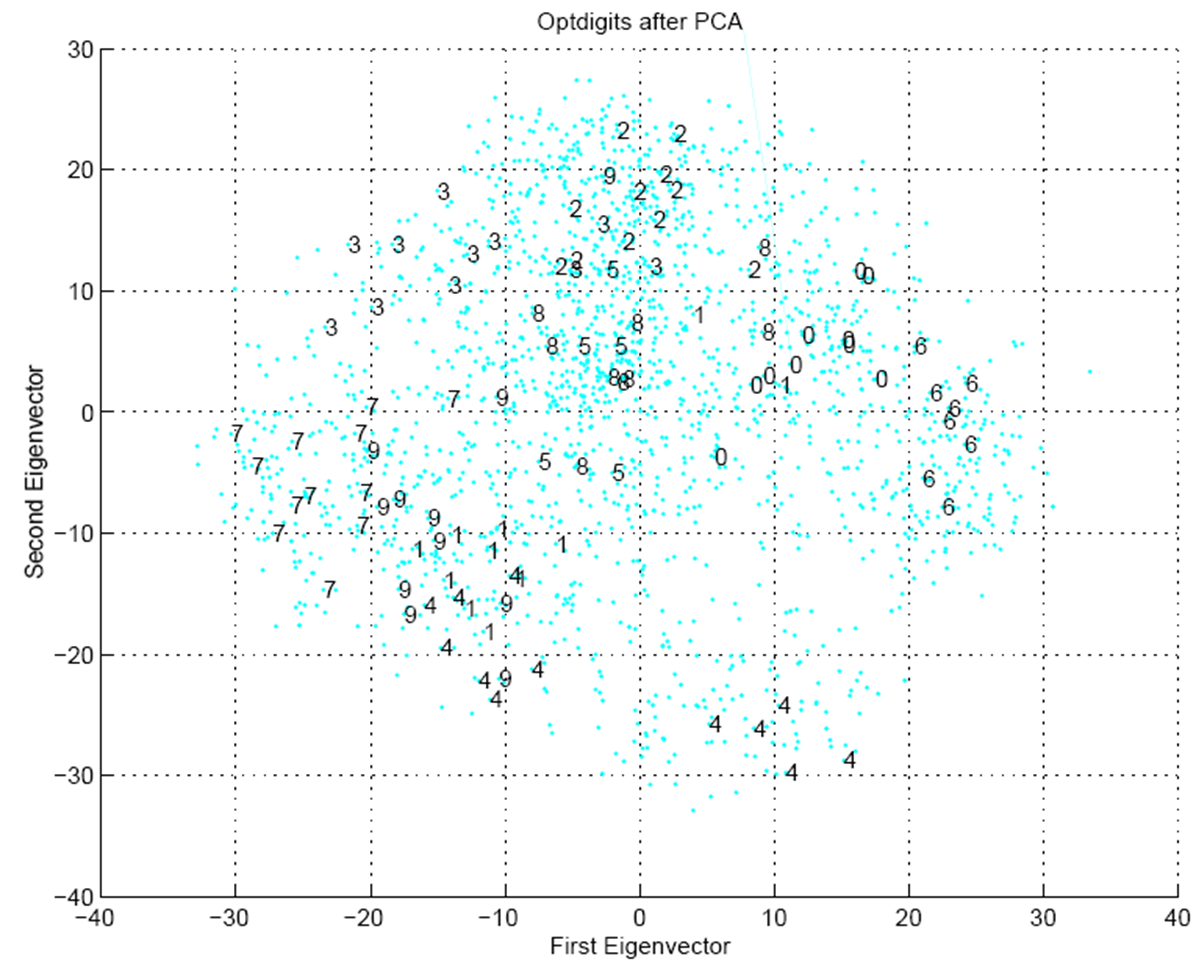

The "elbow" of the scree graph suggest a good choice for $k$.  For visualisation purposes, $k=2$ or $3$.

## Multidimensional Scaling (MDS)

MDS really describes an entire family of techniques (and it's a bit confusing to understand the differences!)

Start with the goal of performing dimensionality reduction on $d$-dimensional data, $\mathcal{X}$, transforming it into $k$-dimensional data $Z$.  Think about doing this on the basis of distances between points - we want to find a mapping that preserves the pairwise distances:

[Least squares or Kruskal-Shepard scaling]

Gradient descent is used to minimize this function (optimize over position of points in $Z$).  There isn't anything specific about the orientation of the points in $Z$, so solutions are not unique.

If we have Euclidean distances in $\mathcal{X}$ and $Z$then the solution will be a linear transformation.  Sounds pretty similar to PCA?

- PCA done on the correlation matrix rather than the covariance matrix is the same as MDS where the data has been standardized (each variable has unit variance).

The variety of MDS formulations come from considering different optimization criteria (stress functions), non-Euclidean (dis)similarities, etc.

The Sammon mapping cares more about preserving smaller distances than larger ones.

## Fisher's Linear Discriminant Analysis

Fisher's LDA is a **supervised dimensionality** reduction technique for classification problems (where $k=1$).  It aims to find a direction, $\mathbf{w}$ such that, when we project the data onto $\mathbf{w}$, the classes are well-separated.

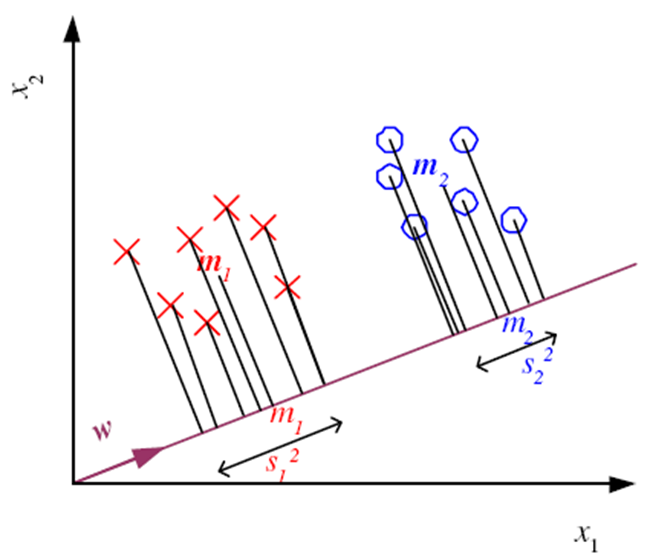

Find the $\mathbf{w}$ that maximizes:

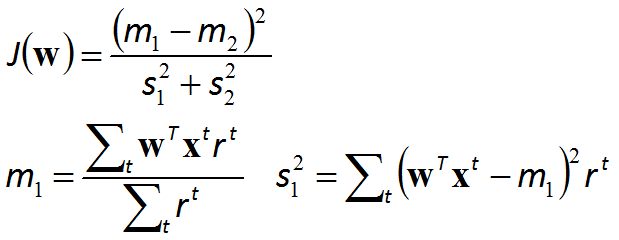

Between class scatter:

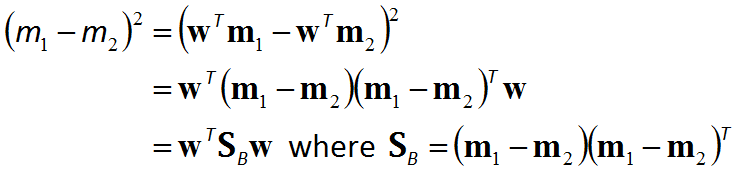

Within class scatter:

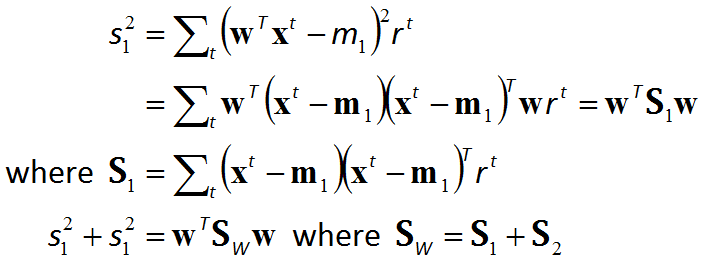

Now rewrite $J$:

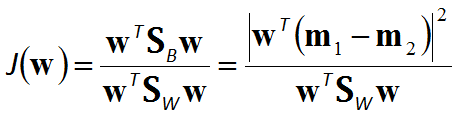

The LDA solution:

%Take the Iris dataset
load fisheriris.mat
%Work on two of the features and two classes
X = meas(1:100,1:2);
m1 = mean(X(1:50,:))

m1 =     5.0060    3.4280


m2 = mean(X(51:100,:))

m2 =     5.9360    2.7700


S1 = cov(X(1:50,:))

S1 =     0.1242    0.0992
    0.0992    0.1437


S2 = cov(X(51:100,:))

S2 =     0.2664    0.0852
    0.0852    0.0985


Sw = S1+S2

Sw =     0.3907    0.1844
    0.1844    0.2422


%The LDA solution
w = inv(Sw)*(m1-m2)'

w =    -5.7182
    7.0715


%Now to plot the result
%Need to move w into view (only it's orientation matters)
wscaled = w/norm(w)

wscaled =    -0.6288
    0.7776


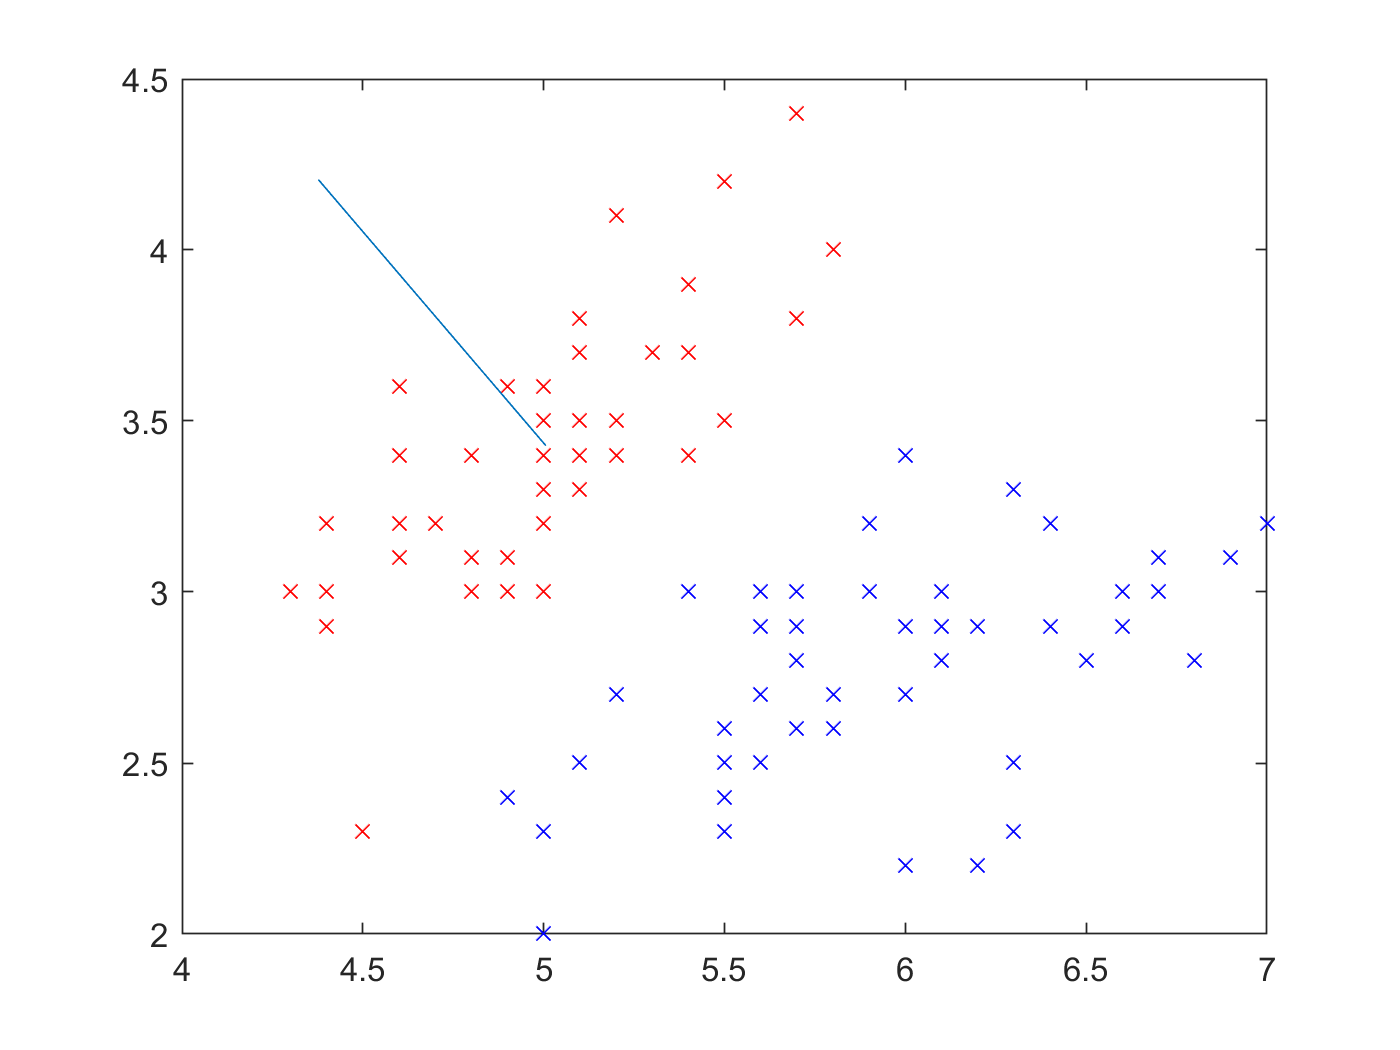

clf
plot(X(1:50,1),X(1:50,2),'rx')
hold on
plot(X(51:100,1),X(51:100,2),'bx')
line([m1(1), m1(1)+wscaled(1)],[m1(2), m1(2)+wscaled(2)])

But didn't we already do LDA!?  The parametric solution:

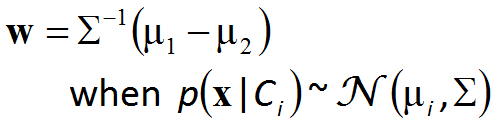

so Fisher's LDA is optimal when the classes are Gaussian distributed.

When we have $K$ classes, we end up with a matrix, $W$ and the projection is down to $K-1$ dimensions.

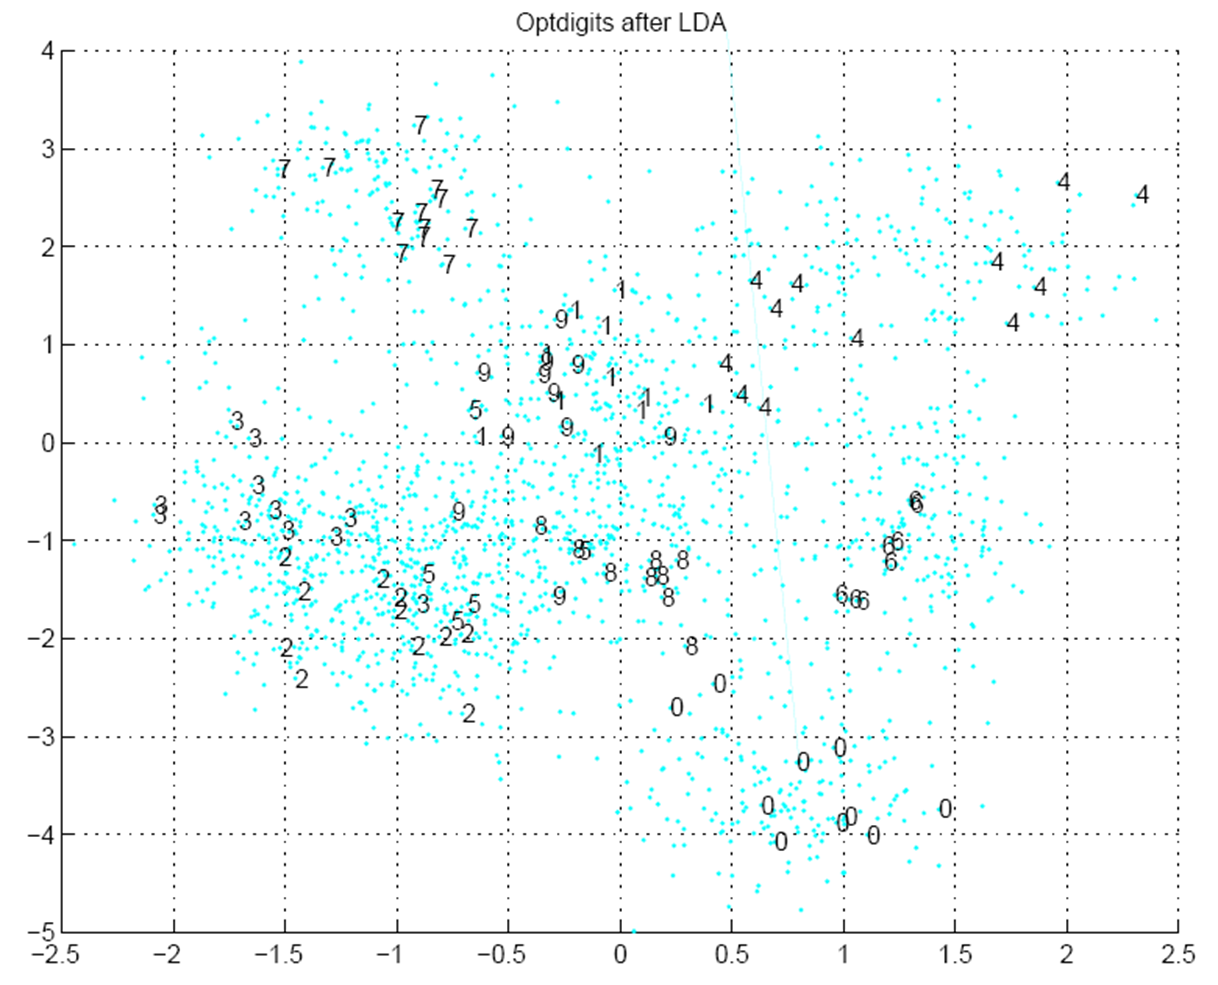

## ISOMAP

If we get time we will have a quick look at ISOMAP.

## t-Stochastic Neighbor Embedding (t-SNE)

We will look at the paper as we discuss this.  Key steps:

- Convert distances between points in the original data space into conditional probabilities representing similarities.

- Think of a similar distribution in the reduced dimension space.

- Minimize the KL divergence between these distributions, using gradient descent.

- t-SNE (v's SNE) uses a symmetrized KL divergence and a t-distribution rather than a Gaussian.